# ELF Demo

This is a demonstration of ELF, the Extensible Lab Framework. It's a work in progress.

## Installation and Setup

First, run setupELF.m -- this will add the framework and all dependencies to your path:

ELFdir = setupELF; % Add ELF classes, BioSigKit, HRVAS, &c. to path

(You should only have to run it once.)

Make sure you're in the right folder to see the example data:

cd(fullfile(ELFdir,'Example')); % Go to folder of example files

## Analyzing HRV, the ultra-fast version

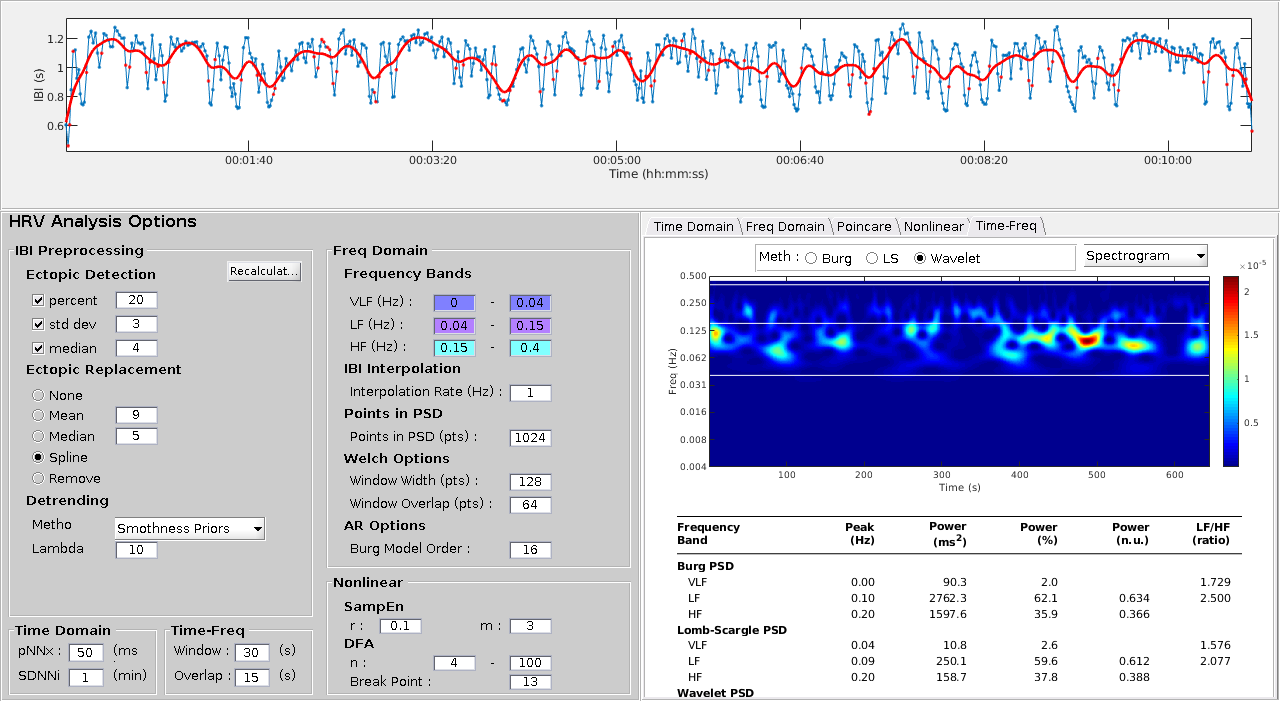

Physio = ELF.Physio('mindware_physio.mw'); Physio.hrvGui;

This will:

    -Import the data

    -Try to find the ECG channel

    -Detect R wave peaks

    -Calculate inter-beat intervals

    -Perform HRV analysis

    -Show you sexy graphs

Of course, a lot of things could go wrong in that process. Naturally, you can examine the intermediate steps -- what, did you think this was all one 80000-line script with no error-checking or documentation?

## Analyzing HRV, step by step

Physio = ELF.Physio; % Make an empty ELF.PhysioData object named Physio

This (new) PhysioData has no file yet (useful for creating a bunch in a loop with different file names, more on that later) -- assign it one like so:

Physio.sourcepath = 'mindware_physio.mw'; Physio.sourcepath

ans = '/home/tom/ELF/Example/mindware_physio.mw'

Note that the full file path is stored, even though you only passed in the name of a file in the current folder. ELF can run from anywhere.

Now read that file:

Physio.importFromPath; % Read the mindware file, store in Physio.raw_data_tt

Note that this also works for other kinds of file, notably bare IBI series (.ibi) and MindWare realtime HRV tables (.txt).

By default, ELF will look for the first channel in the .mw file matching 'ECG' for ECG data -- what if the file has more than one, or they're named something different?

Physio.pickChannels; % Assign ECG, RESP, GSC, EMG channels.
                     % Won't work if .mw not read yet!
Physio.channel_names

ans = struct with fields:
     ecg: 'Ch_1_ECG'
    resp: 'Ch_3_RESP'
     gsc: 'Ch_8_GSC'
     emg: 'EMG'


Note that a Physio object only bothers with one of each type of channel it can understand -- for, say, dyads whose physio is all in one .mw file, you can create a second PhysioData from the same file, and pick different channels.

Now we're ready to clean some data. First de-noise the ECG:

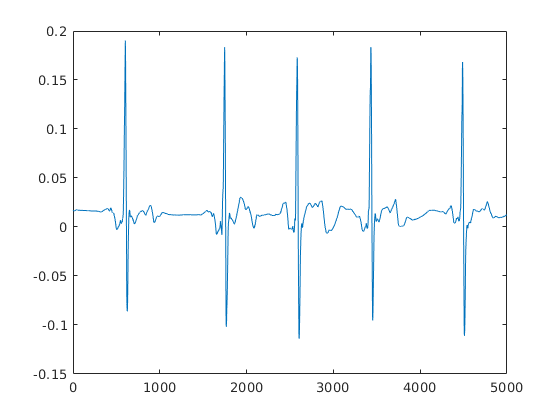

Physio.ecgFromMw;         % Extract ECG channel, de-noise, store in P.ecg
figure; plot(Physio.ecg(1:5000)); % Plot first 5 seconds

Next, run the automatic R-Peak / IBI detection:

Physio.ibisFromEcg;    % Calculate IBI series from ECG signal
Physio.ibis_tt(120:130,:) % Show 10 inter-beat intervals

ans = 11×1 timetable
       Time          IBI   
    __________    _________

    124.45 sec    1.176 sec
    125.57 sec     1.12 sec
    126.63 sec    1.057 sec
    127.8 sec     1.165 sec
    128.97 sec    1.174 sec
    130.04 sec    1.069 sec
    131.07 sec    1.036 sec
    132.24 sec    1.168 sec
    133.39 sec    1.145 sec
    134.58 sec    1.196 sec
    135.52 sec    0.933 sec


Now, that *should* be enough to continue on to HRV analysis, but alas, R-wave detection is not always absolutely perfect. You can hand-correct the beats like so:

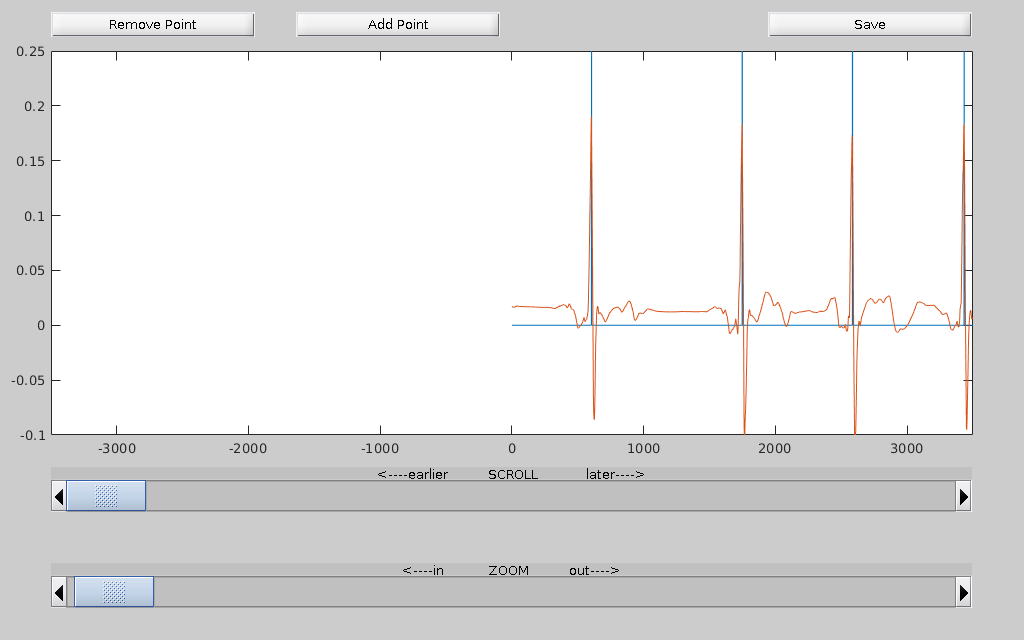

Physio.fixBeats; % Hand-correct IBI series

All right, satisfied now?

Physio.hrvFromIbis; % Calculate HRV data, stored in P.hrv_tt
Physio.hrv_tt       % Show HRV stats by second

ans = 645×8 timetable
     Time      RSA      HFPower    LFPower    LFHFRatio    SDNN     RMSSD    NN50    pNN50
    ______    ______    _______    _______    _________    _____    _____    ____    _____

    1 sec     5.8126    334.48     1727.4      5.1643      166.4    142.5     59     50.9 
    2 sec     5.9396    379.78     1957.7      5.1548      166.3    139.7     59     50.9 
    3 sec     5.9887    398.88     2180.6      5.4667      165.7    140.9     60     51.7 
    4 sec     5.9691    391.14     2386.6      6.1018      164.8    139.7     60     51.7 
    5 sec     5.8902    361.49     2566.

You can export these summary tables to any convenient format:

Physio.exportHrv('hrv_table.csv');  % Save as .csv
Physio.exportHrv('hrv_table.xlsx'); % Save as .xlsx

Or save the whole PhysioData object like so:

Physio.save('My_Physio');

This is highly recommended, as it saves running all those steps again.

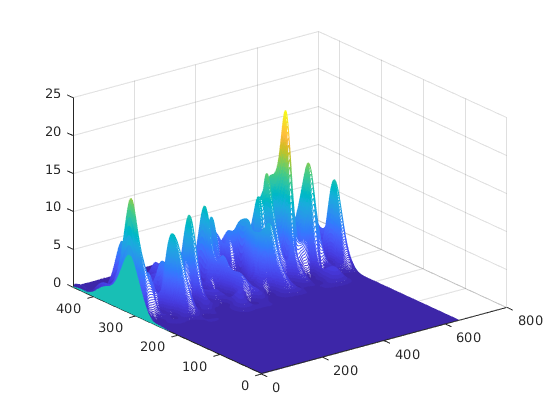

clear Physio; % Erase the PhysioData object P from the workspace
Physio=ELF.Physio.ELFopen('My_Physio'); % Get it back
figure; waterfall(Physio.psd) % Plot power spectrum densities as mesh, no recalc necessary

Once you have HRV stats, you can calculate them for any windows of time:

Windows=ELF.Windows([20,30;40,50;70,80]); % Select windows (more on Windows below)
Windows=Physio.hrvWinStats(Windows,'WinVars',{'RSA'}) % Mean RSA between seconds 20-30, 40-50, 70-80

Windows = 1×3 table
    Win1_mean_RSA    Win2_mean_RSA    Win3_mean_RSA
    _____________    _____________    _____________

        4.444           5.7299           4.8445    


Which stats are available for windowing?

Physio.hrv_vars

ans = 1×8 cell array
    {'RSA'}    {'HFPower'}    {'LFPower'}    {'LFHFRatio'}    {'SDNN'}    {'RMSSD'}    {'NN50'}    {'pNN50'}


What if you want more than one?

Windows = ELF.Windows([120,180;180,240]);
Physio.hrvWinStats(Windows,'WinVars',{'RSA','LFPower','HFPower'})

ans = 1×6 table
    Win1_mean_RSA    Win1_mean_LFPower    Win1_mean_HFPower    Win2_mean_RSA    Win2_mean_LFPower    Win2_mean_HFPower
    _____________    _________________    _________________    _____________    _________________    _________________

       5.0161             1326.5               158.43             4.7784             653.73               162.09      


    % Mean RSA, LFHRV, and HFHRV in minutes 2 and 3

What if it's not the *mean* you want?

Physio.hrvWinStats(ELF.Windows([0,60]),'WinVars',{'RSA'},'WinFunc',@max)

ans = table
    Win1_max_RSA
    ____________

       6.3231   


    % Max RSA in first minute

You can pass any vector function, including your own.

But what if the window starts and ends are different for every recording, you might well might plaintively ask?

## Finding Windows in Event Data

Read an E-Prime event file like so:

Events=ELF.Events('mindware_events.txt');
Events.events_tt

ans = 23×2 timetable
       Time       EventType          EventName      
    __________    _________    _____________________

    0.001 sec         0        'acquisition started'
    9.33 sec         46        'Threat35'           
    44.329 sec       10        'End'                
    55.413 sec       37        'Neutral47'          
    102.41 sec       10        'End'                
    112.61 sec       55        'Power23'            
    135.61 sec       10        'End'                
    147.34 sec       35        'Neutral23'          
    170.34 sec       10        'End'                
    180.03 sec       57        'Power47'            
    227.03 sec       10        'End'                


Find windows between all events matching Neutral, Power, or Threat and the next End event

Windows=Events.winsBetween({'Neutral','Power','Threat'},'End');
Physio.hrvWinStats(Windows,'WinVars',{'RSA','SDNN'})


ans =

  0×0 empty table



## Adding Behavioral Data

Read an E-STUDIO experiment text log like so:

Behav = ELF.Behav('eprime_behav_edat.txt');

This will give you a big table of all the information from the run:

% Behav.edat_t % Everything (mostly NaNs)

You can query this like any table, but there are also some pre-made methods for narrowing it all down:

Behav.taskevents_t % Just data with matching event numbers

## Putting it All Together

Combine all three data analysis objects you've created into one Task object:

sources.Physio = Physio;
sources.Events = Events;
sources.Behav = Behav;
Task = ELF.Task('DemoTask',sources)

Task objects come with lots of helpful methods to combine data:

%TODO

So there you have it: once you've defined a Task, you can query it for all the data you like. Of course, it's no fun to do that one task at a time...

## Batch Processing

Task sources can be tables of data from many particpiants:

%TODO

This means you can repeat an operation for all the Physio, or all the Events:

%TODO

It also means you can repeat a row function combining data from all three, once per participant:

%TODO

Not enough RAM in your laptop to hold so much data? Note that large tables ELF objects can be saved as files, and opened one at a time, without any change in syntax:

%TODO

## Combining Multiple Tasks in a Study

%TODO

From here you can grab a table of all your study data, suitable for export to SPSS or similar:

%TODO

...Or, you could use the built-in hypothesis tester:

%TODO

And don't forget the pretty graphs:

%TODO

In summary, for any given study, you can define parameters and process all your files at once. You can even start doing it before you're done collecting data -- as soon as you have the variables you want from one set of pilot data, it all runs on automatic. A few minutes after your very last participant run, you have your analysis in hand. Kinda takes the pressure off, right?

## Graphical User Interface

Sometimes scripts are too hard, and you just want to push buttons like a chump. ELF has you covered! Each data class has a GUI:

% These will open nice friendly interfaces to ELF classes, with a blank/empty object by default:

% PhysioDataGui;
% EventDataGui;
% BehavDataGui;
% TaskGui;
% StudyGui;

You can also pass them objects to display:

% PhysioDataGui(P);
% EventDataGui(E);
% BehavDataGui(B);
% TaskGui(T);
% StudyGui(S);

Or tell an object to launch its own:

% P.gui;
% E.gui;
% B.gui;
% T.gui;
% S.gui;

Extending the Framework

Now that you've seen how ELF data objects work, you can modify them or create your own! Anything you put in the ExtensibleLabFramework/+ELF folder will be available to you.

cd(fullfile(ELFdir,'+ELF')); ls % List files in ELF package folder

Those folders beginning with @ are the class definitions and functions for each object type. Let's take a look at PhysioData:

cd @PhysioData; ls % List files in PhysioData class folder

PhysioData.m contains the class definition, which includes a listing of all the variables a PhysioData object can hold (Properties) and all the functions it knows how to perform on them (Methods).

properties(ELF.PhysioData) % List available properties of PhysioData objects

Note that PhysioData doesn't actually store that many properties! Most of them are *dependent* properties -- for instance, the de-noised ECG signal stored in P.ecg is also available as a MATLAB timetable in P.ecg_tt -- 

P.ecg(1:10) % First ten seconds of ECG as simple vector
P.ecg_tt(1:10,:) % First ten seconds of ECG as timetable

-- but it isn't *stored* twice. This is because PhysioData.m defines a *getter* method called get.ecg_tt, which creates the timetable from the master copy in P.ecg. The same thing applies to IBI series: a master copy is stored in P.ibis as a simple vector of numbers, but you can grab it as an array or a table:

P.ibis(1:10) % First ten inter-beat intervals
P.ibis_a(1:10,:) % 2-column array of [beats ibis]
P.ibis_tt(1:10,:) % MATLAB timetable of same

The advantage of this is that you can adapt to many different external frameworks (some expect IBIs in seconds, some in miliseconds, some horizontal, some vertical, some with a corresponding column of beat times, &c. &c.). If each of those formats were stored independently, they'd get out of sync -- it'd be easy to modify one and forget to modify the others.

Properties and their default values are named in a block (between 'properties' and 'end') at the top of the class definition file (in this case +ELF/@PhysioData/PhysioData.m). Dependent properties to be calculated on demand are named in another such block (between 'properties (Dependent)' and 'end'), and their getter methods are defined separately (in a 'methods' block).

You can add your own! A dependent property can be defined like so:

% (inside +ELF/@PhysioData/PhysioData.m)
% % ...
% properties (Dependent)
%     % ...
%     ibis_in_ms %calculated on the fly
%     % ...
% end
% % ...
% methods
%     % ...
%     function ibis_in_ms = get.ibis_in_ms(P)
%         ibis_in_ms = P.ibis .* 1000;
%     end
%     % ...
% end

To query your new dependent property, you don't have to pass the P object -- it's assumed you mean the one you're calling from:

% P.ibis_in_ms % Convert P.ibis to milliseconds

Note that when you define a new dependent property in the class definition, it is *instantly* available to all existing objects of that class:

% Some_Other_P.ibis_in_ms

This means you can extend to your heart's content, without wrecking all your old data!

Class methods allow you to query, preprocess, or otherwise transform the data stored in properties.

methods(ELF.PhysioData) % List all available methods for PhysioData objects

 Methods can be defined either in the class definition file or in separate files, and can call each other. Define inside the class definition file like so:

% (inside +ELF/@PhysioData/PhysioData.m)
% % ...
% methods
%     % ...
%     function changeEcgChannelAndReclean(P,new_ecg_channel_name)
%         if nargin<2; new_ecg_channel_name = 'ECG';
%         P.ecg = [];
%         P.ibis = [];
%         P.cleaner = '';
%         P.channel_names.ecg = new_ecg_channel_name;
%         P.ecgFromMw();
%         P.ibisFromEcg();
%         P.fixBeats();
%     end
%     % ...
% end

% P.changeEcgChannelAndReclean('Ch_6_ECG');

Note that you don't have to pass the object as an argument when calling, but you do have to count when setting defaults with nargin.

If that function were longer, it might make sense to store it in a separate file -- just put it in the class folder (@PhysioData) and add a reference to the class definition:

% (inside +ELF/@PhysioData/PhysioData.m)
% % ...
% methods
%     % ...
%     changeEcgChannelAndReclean(P,new_ecg_channel_name)
%     % ...
% end

% (inside +ELF/@PhysioData/changeEcgChannelAndReclean.m)
% function changeEcgChannelAndReclean(P,new_ecg_channel_name)
%     if nargin<2; new_ecg_channel_name = 'ECG';
%     P.ecg = [];
%     P.ibis = [];
%     P.cleaner = '';
%     P.channel_names.ecg = new_ecg_channel_name;
%     P.ecgFromMw();
%     P.ibisFromEcg();
%     P.fixBeats();
% end

% P.changeEcgChannelAndReclean('Ch_6_ECG');

Note that the reference to the external method in the class definition does not include 'function' or 'end' -- just result=methodname(obj,args).

As with properties, changes to methods are immediately available to all objects. External files are easier to debug -- if the class file is in an inconsistent state (e.g. if it has a half-written function with a 'for' but no 'end'), it won't work for anything, but if your external method is buggy it'll only interfere with the rest when you call it:

% (inside +ELF/@PhysioData/PhysioData.m)
% methods
%     function unfinishedFunc(P)
%        if( %TODO
%     end
% end

% P.unfinishedFunc() % Throws error
% P.ibis % Also throws error

% VERSUS

% (inside +ELF/@PhysioData/PhysioData.m)
% methods
%     unfinishedFunc(P)
% end

% (inside +ELF/@PhysioData/unfinishedFunc.m)
% function unfinishedFunc(P)
%     if( %TODO
% end

% P.unfinishedFunc() % Throws error
% P.ibis % Still works

Getter/setter methods must be defined inside the class definition, and not in separate files. The same is true of *static* class methods, which are functions you can call without actually having created an object. For example, if you'd like to use ELF's beat detection functionality without all the rest, you can do it like this:

some_ecg_sig = P.ecg; % Make a copy
some_ibis = ELF.PhysioData.ecg2ibi(some_ecg_sig); % Can pass it an ECG sig you got somewhere else

This allows for some flexibility in working with other peoples' software. Static methods are defined in a block in the class definition file (between 'methods (Static)' and 'end').

## FAQ

-Can I modify this for my own use?

Yes.

-How do I work with a new type of data?

Write an object definition according to the template in TODO. Import the file however you can (see if someone else has already written an importer). Define dependent properties and their getters, have them return tables. Add methods to @Task to cross-correlate data from those tables with other data types.

-Why is everything tables?

They can store heterogeneous data types with variable names, and they make it easy to select subsets of one variable based on another.

-How do I write a custom gathering function for a task?

% function value = myfunc(T)
%     P = T.physio_data
%     B = T.behav_data
%     value = B.something * P.something
%     &c &c
% end
% functionnametocome(@myfunc, ...)

-Doesn't that get memory-intensive?

All the objects inherit the handle class, so the data is not being recopied. If you set more than one variable equal to an object, they all refer to the same object.

-Why the silly acronym?

Because I couldn't get away with calling it the Tom Wilson Analysis Toolkit.